**MARÇAL Thomas                                                                            Groupe de TD : P**

**MARQUET Thomas**

# **SUJET : Etude d'un pendule pesant simple**

**Membres du groupe : **

- MARÇAL Thomas

- MARQUET Thomas

clear all

(Veuillez lancer cette partie avant de lancer le modèle SIMULINK et SIMSCAPE)

$\Longrightarrow$ On pose les données suivantes pour toutes la suite de l'étude :

Données physiques :

g = 9.81; % (en m/s^2) g représente l'intensité de la pesanteur terrestre
K = 1; % (en s^(-1)) K représente le coefficient de frottement visqueux de l'air

Données de l'étude (Modifiable) :

theta0 = pi/4; % (en rad) theta0 représente l'angle initial d'écartement de la masse m  
m = 0.5; % (en kg) m représente la masse accroché au bout du fil du pendule
l = 0.1; % (en m) l représente la longueur du fil
w0 = sqrt(g/l);

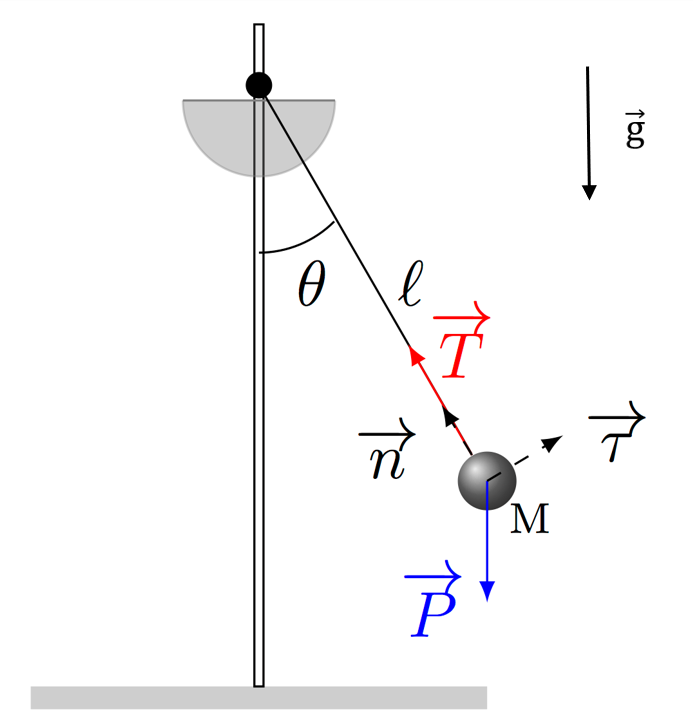

**1/ On suppose que les frottements de l'air sont négligés.**

Soit l'equation différentielle qui régit la dynamique du mouvement pour le pendule simple pesant : 

### 
$$\frac{d{\theta \left(t\right)}^2 }{d^2 t}\;=\;-\frac{g}{l}*\sin \left(\theta \left(t\right)\right)$$
         
$$\left(I\right)$$


On en déduit dans le cas des petites oscillations ( $\sin \left(\theta \right)\simeq \theta$ ), une solution analytique de l'équation $\left(I\right)$ :

### 
$$\theta \left(t\right)=\theta_0 *\cos \left(\omega_{0\;} *t\right)$$
        
$$\left(\textrm{II}\right)$$


avec :

-  
$$\theta_0 =\theta \left(t\;=\;0\right)$$


- $\omega_0 =\sqrt{\frac{g}{l}}$ ; la pulsation

**a. On souhaite résoudre l'équation différentielle **$\left(I\right)$** avec MATLAB.**

On transforme notre équation différentielle $\left(I\right)$ en systeme d'equation du premier ordre, pour pouvoir la résoudre avec **ode45**.

On pose : 

#### 
$$$$
\ \left\{
    \begin{array}{ll}
        \theta_{1}(t) & = \theta(t) \\
        \theta_2 (t)& \mbox{= $\frac{\partial \theta(t)}{\partial t}$}
    \end{array}
\right.
$$$$


D'où : 

#### 
$$$$
\ \left\{
    \begin{array}{ll}
        \frac{\partial \theta_{1}(t)}{\partial t} & \mbox{= $\frac{\partial \theta(t)}{\partial t}$} \\
         \frac{\partial \theta_{2}(t)}{\partial t} & \mbox{= $\frac{\partial \theta(t)^2}{\partial^2 t}$}
    \end{array}
\right.
$$$$


On obtient donc le systeme suivant : 

#### 
$$$$
\ \left\{
    \begin{array}{ll}
        \theta_2(t) & \mbox{= $\frac{\partial \theta_1(t)}{\partial t}$} \\
         \frac{\partial \theta_{2}(t)}{\partial t}  + \frac{g}{l} * sin(\theta_1(t))& \mbox{= 0}
    \end{array}
\right.
$$$$


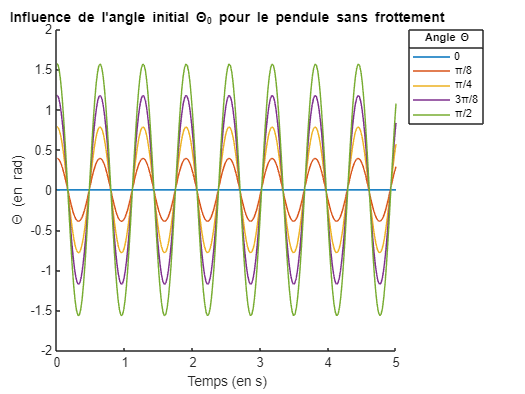

clf

for theta = 0:pi/8:pi/2
    fun1 = @(t,w) [w(2); -(g/l) * sin(w(1))];
    [tfun1,wfun1] = ode45(fun1,[0,5],[0,theta]);
    
    hold on

    plot(tfun1,wfun1(:,2), 'DisplayName', ['\Theta = ' num2str(theta)])
    
    title("Influence de l'angle initial \Theta_0 pour le pendule sans frottement");
    xlabel('Temps (en s)');
    ylabel('\Theta (en rad)');
    lgd = legend({'0', '\pi/8', '\pi/4','3\pi/8', '\pi/2'},'Location', 'bestoutside');
    title(lgd,'Angle \Theta');

    hold off

end

**Constat et Interprétation : En supposant que les frottements fluides de l'air sont négligeables devant les autres actions mécaniques extérieurs. **

Nous avons un pendule simple libre et non amorti.

Le mouvement du pendule est périodique.

On remarque que : 

- Si $\theta_{0\;} =0$, il n'y a pas d'oscillations.

- Si $\theta_{0\;} \not= 0$, on remarque que l'amplitude $\theta_{0\;}$ des oscillations du pendule est constante. Ainsi, en augmentant l'angle de départ $\theta_{0\;}$, on obtient des oscillations d'amplitudes plus grandes.

On conclut que l'angle initial $\theta_0$ a une influence sur l'amplitude des ocsillations au cours du temps.

**b.** Par défaut, on prend ici : $\theta_{0\;} =\frac{\pi }{4}$ .

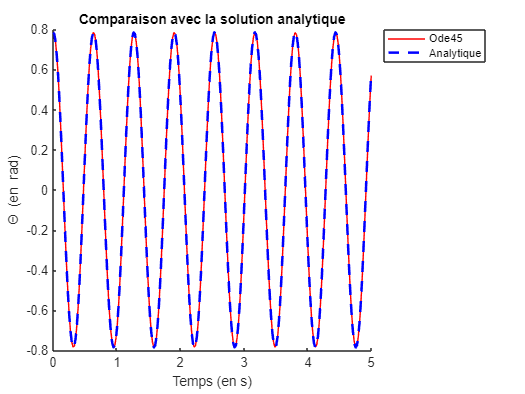

clf

SolAnalytique = @(t) (theta0*cos(sqrt(g/l)*t)); % Equation de la solution analytique donnée par l'énoncé 

fun1 = @(t,w)[w(2); -(g/l) * sin(w(1))];
[tfun1,wfun1] = ode45(fun1,[0,5],[0,theta0]);

hold on

plot(tfun1,wfun1(:,2), 'r')
plot(tfun1,SolAnalytique(tfun1),'--b', LineWidth = 2)

title("Comparaison avec la solution analytique");
xlabel('Temps (en s)');
ylabel('\Theta (en rad)');
legend("Ode45", "Analytique",'Location', 'bestoutside');

hold off

**Constat :** 

On remarque que la solution numérique et la solution analytique sont superposés. 

**Interprétation :**

On a donc très peu d'écart entre la methode ode45 et la méthode analytique. Cela implique que notre méthode de résolution par ode45 est une bonne méthode d'approximation de la solution analytique.

**c. Application SIMULINK**

- **Simulation SIMULINK de la solution analytique du pendule :**

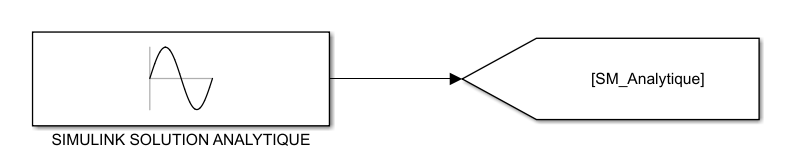

**Pour les petites oscillations (Exemple : **$\theta_0 =\frac{\pi }{32}\;$**) :**

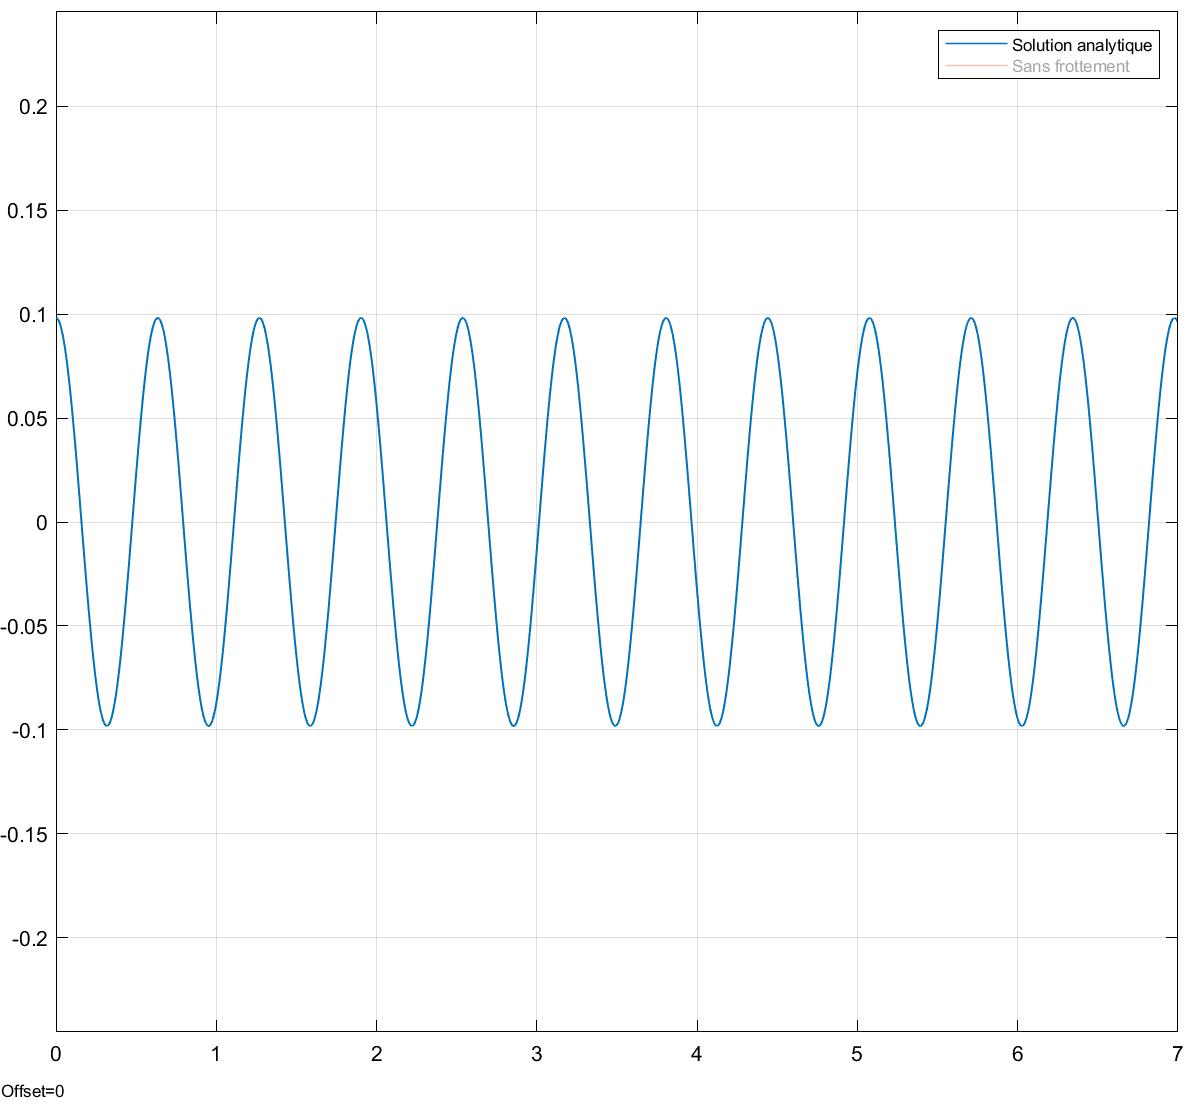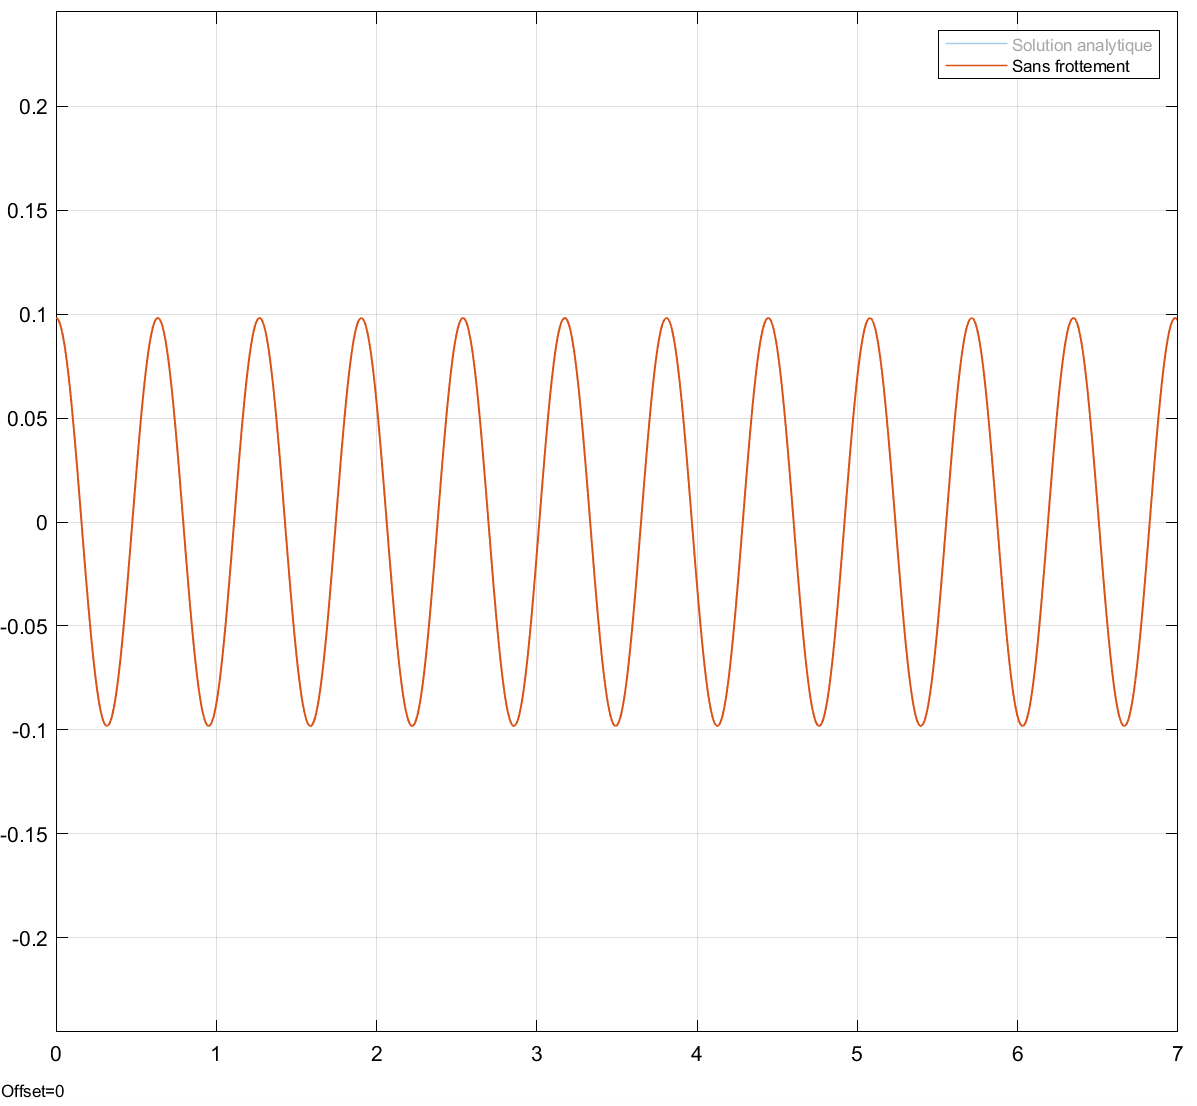

**SOLUTION ANALYTIQUE        |         SOLUTION SIMULINK **

avec $$$
\ \left\{
    \begin{array}{ll}
        \theta~\textit{(en radian) en ordonnée}\\
         \textit{t}~\textit{(en seconde) en abscisse}\\
    \end{array}
\right.
$$$ 

On remarque que les deux solutions sont superposables l'une à l'autre.

**Pour les grandes oscillations (Exemple : **$\theta_0 =\frac{\pi }{4}\;$**) :**

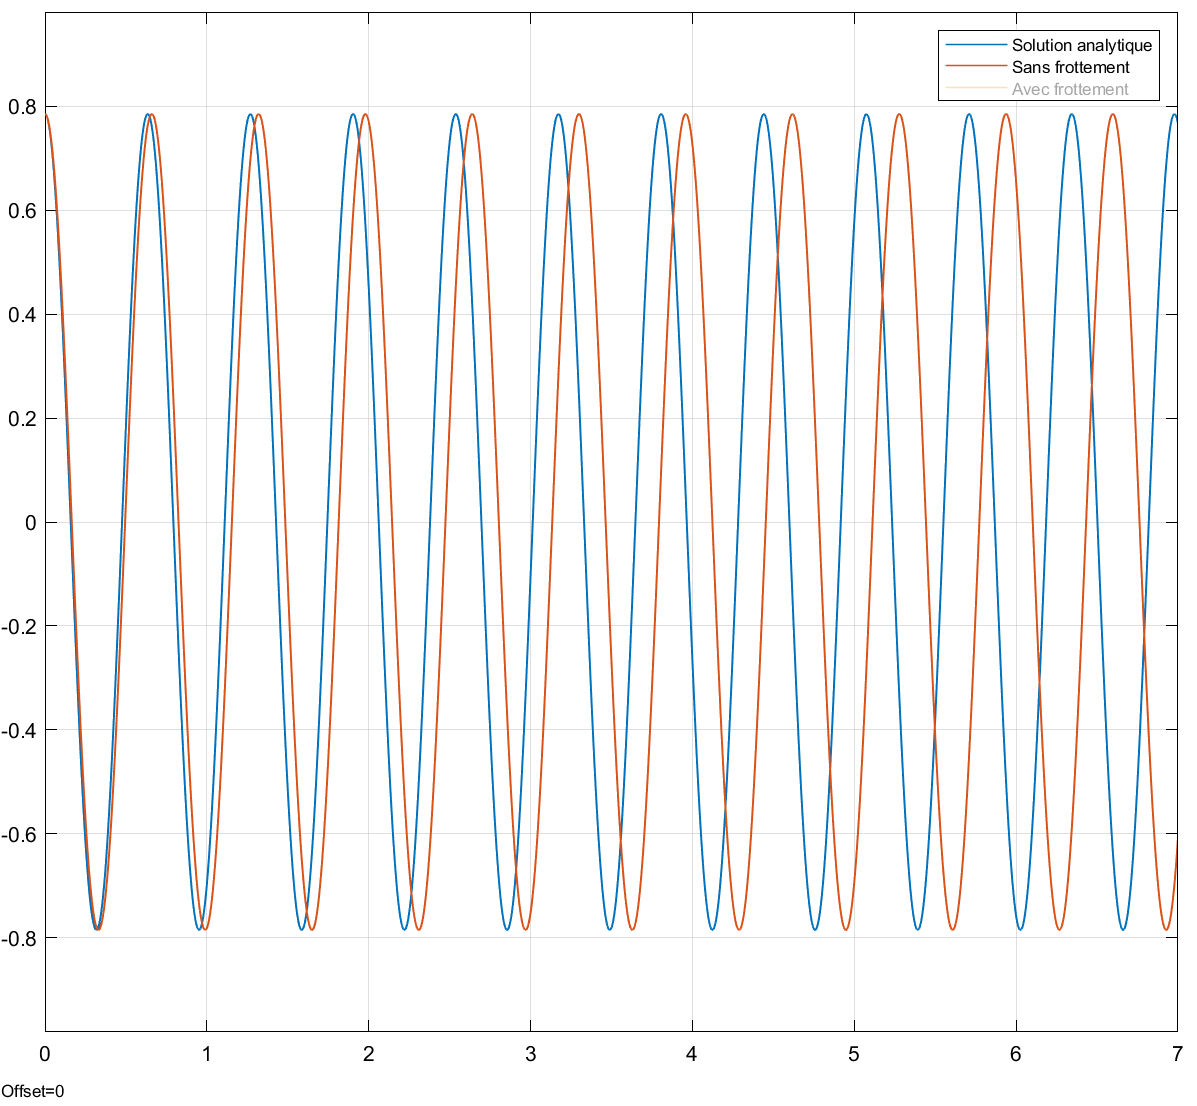

avec $$$
\ \left\{
    \begin{array}{ll}
        \theta~\textit{(en radian) en ordonnée}\\
         \textit{t}~\textit{(en seconde) en abscisse}\\
    \end{array}
\right.
$$$ 

On remarque que les deux courbes ne sont plus superposables

- **Simulation SIMULINK du pendule sans frottement :**

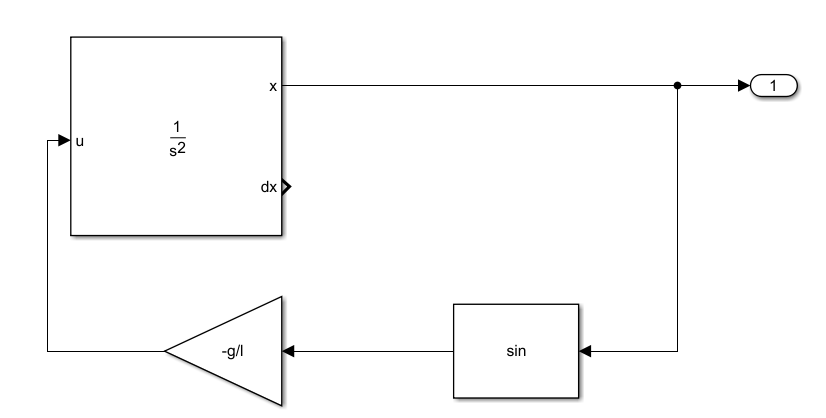

$\Rightarrow$**Résultat :** 

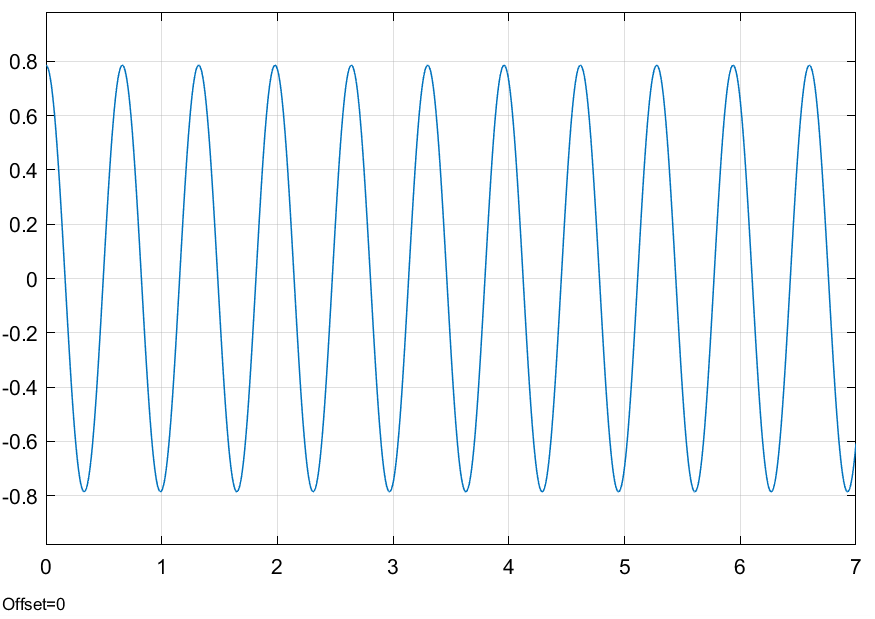

avec $$$
\ \left\{
    \begin{array}{ll}
        \theta~\textit{(en radian) en ordonnée}\\
         \textit{t}~\textit{(en seconde) en abscisse}\\
    \end{array}
\right.
$$$ 

**Comparaison des résultats : **

En reprenant les courbes trouvées en **1.b/** pour $\theta_0 =\frac{\pi }{4}$, on remarque que les courbes obtenues pour la modélisation du pendule via SIMULINK, possède la même allure que l'ensemble des courbes trouvés en **1.b/**. Plus précisément, notre courbe obtenu via SIMULINK coincide en tout point. 

Or, dans le cadre de la simulation SIMULINK pour modéliser la solution analytique, on constate 2 cas.

Nous pouvons constater que notre solution est correcte lorsque nous sommes dans le cas des petites oscillations ($\sin \left(\theta \right)\simeq \theta$). En effet, afin d'élaborer cette solution analytique, nous avons pris en compte le cas des petites oscillations pour simplifier le problème.

Lorsque nous prenons le cas de plus grandes oscillations, nous constatons qu'il y a un déphasage qui se crée, et qui illustre que la solution analytique ne respecte plus le véritable mouvement du pendule, car l'hypothèse des petites oscillations n'est plus respectée.

**Conclusion :**

Le modèle expérimental est correcte en tout point. Ce qui n'est pas le cas de la solution anlaytique, où le résultat diffère en fonction de l'angle $\theta$, car l'hypothèse des petits angles (sin($\theta$) = $\theta$) dans certains cas n'est plus respectée.

**2/ On suppose que le frottement de l'air est dorénavent pris en compte. **

**a. On souhaite résoudre l'équation différentielle avec la prise en compte des frottements de l'air avec MATLAB.**

L'equation différentielle du mouvement devient alors : 

### 
$$\frac{d{\theta \left(t\right)}^2 }{d^2 t}\;=\;-\frac{g}{l}*\sin \left(\theta \left(t\right)\right)-\frac{k}{m}*\frac{d\theta \left(t\right)}{\textrm{dt}}$$
         
$$\left(\textrm{II}\right)$$


où : $k=1\;s^{-1} \;$ le coefficient de frottement visqueux de l'air.

- On fait ici varier l'angle $\theta_0$ :

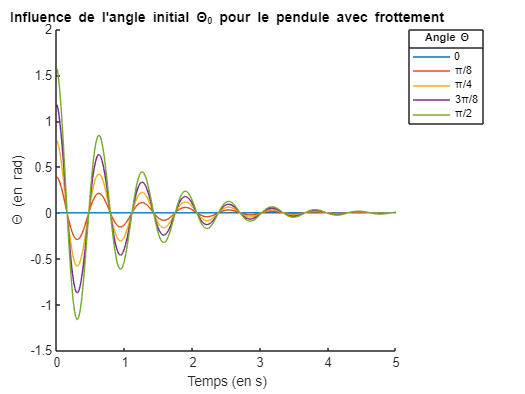

clf

for theta = 0:pi/8:pi/2

    fun1 = @(t,w)[w(2); -(g/l) * sin(w(1)) - (K/m)*w(2)];
    [tfun1,wfun1] = ode45(fun1,[0,5],[0,theta]);

    hold on

    plot(tfun1,wfun1(:,2), 'DisplayName', ['\Theta = ' num2str(theta)]);
    title("Influence de l'angle initial \Theta_0 pour le pendule avec frottement");
    xlabel('Temps (en s)');
    ylabel('\Theta (en rad)');
    lgd = legend({'0', '\pi/8', '\pi/4','3\pi/8', '\pi/2'},'Location', 'bestoutside');
    title(lgd,'Angle \Theta');

    hold off

end

- On fait ici varier la masse m accroché au pendule :

Par défaut, on prend ici : $\theta_{0\;} =\frac{\pi }{4}$ .

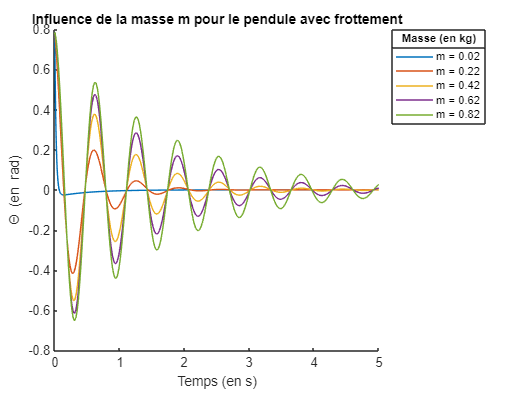

clf

for M = 0.02:0.2:1

    fun1 = @(t,w)[w(2); -(g/l) * sin(w(1)) - (K/M)*w(2)];
    [tfun1,wfun1] = ode45(fun1,[0,5],[0,theta0]);
    
    hold on
    
    plot(tfun1,wfun1(:,2), 'DisplayName', ['m = ' num2str(M)]);
    title("Influence de la masse m pour le pendule avec frottement");
    
    xlabel('Temps (en s)');
    ylabel('\Theta (en rad)');
    lgd = legend('Location', 'bestoutside');
    title(lgd,'Masse (en kg)');

    hold off

end

**Constat : En supposant que les forttements fluides de l'air ne sont plus négligeables devant les autres actions mécaniques extérieurs. **

Nous avons un pendule simple amorti.

On constate plus précisément que la variation de la masse m ou de l'angle initial $\theta_{0\;}$ provoquent les mêmes effets sur le pendule, elles entrainent une décroissance dans les amplitudes du pendule.

Donc, nous avons des oscillations d'amplitudes qui décroissent au cours du temps, dû aux frottements. A la fin, nos deux systèmes, malgré les variations sur les deux opérateurs, convergeront faire une amplitude nulle. 

De plus, on remarque que nous avons deux cas que nous connaissons: 

- Si les oscillations sont **amorties fortement**,  nous avons un mouvement **apériodique**, c'est le cas lorsque m = 0.01 kg.

- Si les oscillations sont **amorties faiblement**, nous avons un mouvement **pseudo-périodique**, c'est ce qui se produit dans les autres cas. 

Dans le cas du mouvement **apériodique**, on ne peut plus mesurer de période, car les forces de frottement sont trop fortes. En effet, on peut remarquer que sur le graphique, il n’y a plus d’oscillation. Le mouvement est donc **apériodique**.

**b. Application SIMULINK**

- **Simulation SIMULINK du pendule avec frottement :**

On reprend le modèle du pensule pesant sans frottement, auquelle on applique le frottement de l'air. 

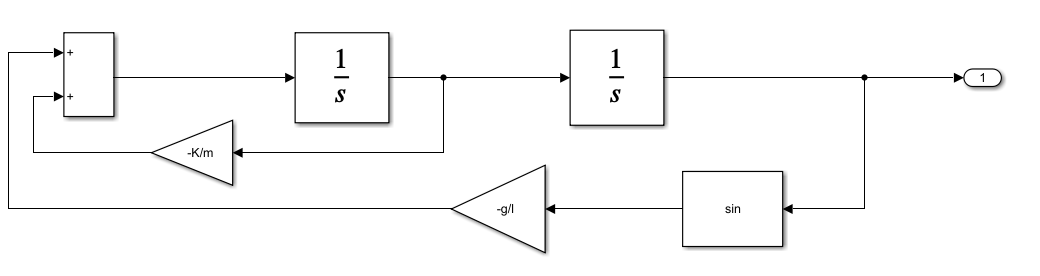

$\Rightarrow$**Résultat :** 

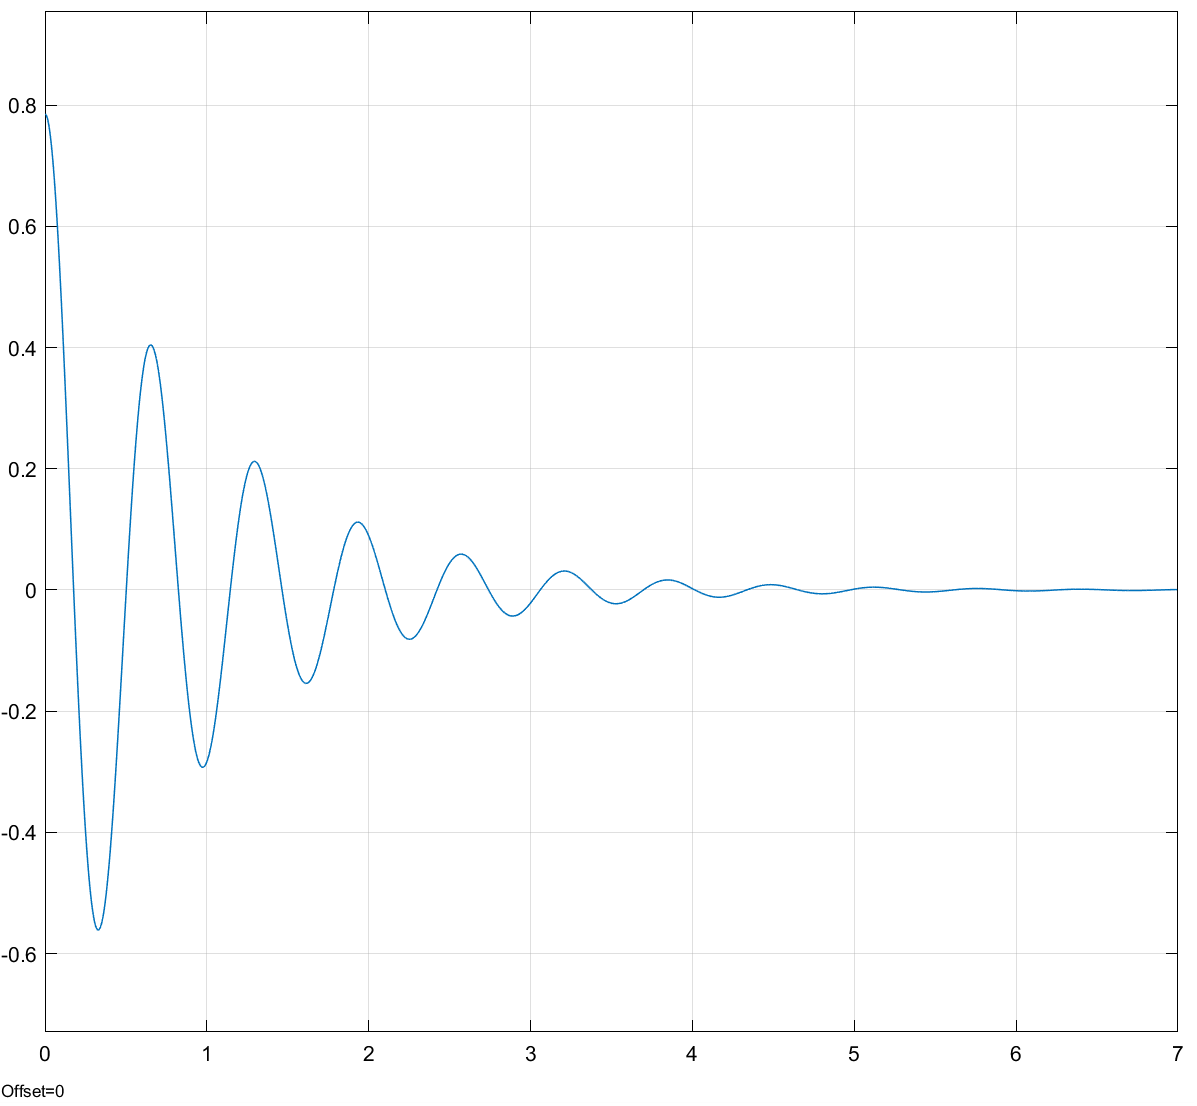

avec $$$
\ \left\{
    \begin{array}{ll}
        \theta~\textit{(en radian) en ordonnée}\\
         \textit{t}~\textit{(en seconde) en abscisse}\\
    \end{array}
\right.
$$$ 

**Comparaison des résultats : **

Donc, en reprenant les courbes trouvées en 2.a/, on remarque que les courbes coincident avec le résultat obtenue à travers SIMULINK. 

En effet, on retrouve bien le fait que notre regime est **pseudo-périodique**, pour les paramètres suivant : $\theta_0 =\frac{\pi }{4}\;;m=0\ldotp 5\;\textrm{kg}\;;l=0\ldotp 1\;m$ , appliqués dans SIMULINK.

Ce qui illustre que notre interprétation par SIMULINK du problème est correcte.

**3/ Conclure sur les différences entre le cas 1/ et le cas 2/.**

- Dans le cas où on ne prend pas en compte les frottements (cas 1), on observe que notre système est **pseudo-périodique**. 

En effet, nous avons un pendule simple libre et non amorti. Le mouvement du pendule est donc périodique, de période : $T=2\pi \sqrt{\frac{l}{g}}$. 

De plus, l'angle initial $\theta_0$ a une influence sur l'amplitude des ocsillations au cours du temps, qui reste constant.

- Dans le cas où on prend en compte les frottements de l'air (cas 2), on observe que notre système est **apériodique**.

En effet, nous avons un pendule simple amorti.

De plus,  la variation de la masse m ou de l'angle initial $\theta_{0\;}$ provoquent une décroissance dans les amplitudes du pendule. Donc, nous avons des oscillations d'amplitudes qui décroissent au cours du temps, dû au frottement, et qui finissent par converger vers une amplitude nulle. 

**4/ Application SIMSCAPE**

**Pendule modélisé :**

                               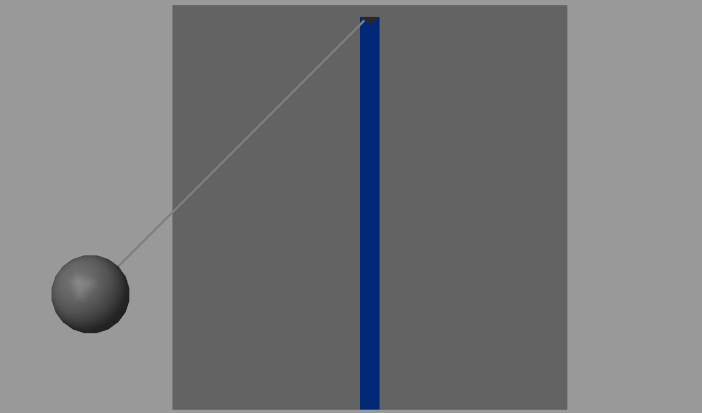

- **Simulation SIMSCAPE du pendule SANS frottement :**

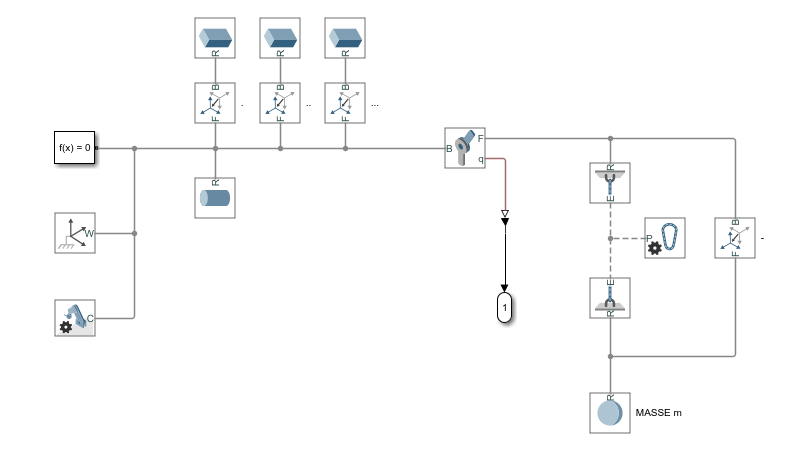

$\Rightarrow$**Résultat :** 

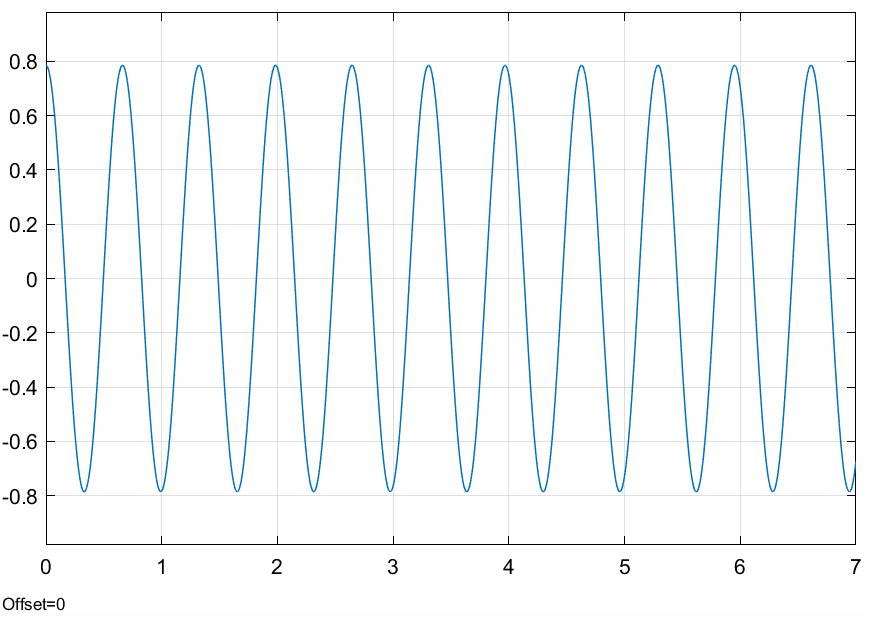

avec $$$
\ \left\{
    \begin{array}{ll}
        \theta~\textit{(en radian) en ordonnée}\\
         \textit{t}~\textit{(en seconde) en abscisse}\\
    \end{array}
\right.
$$$ 

- **Simulation SIMSCAPE du pendule AVEC frottement :**

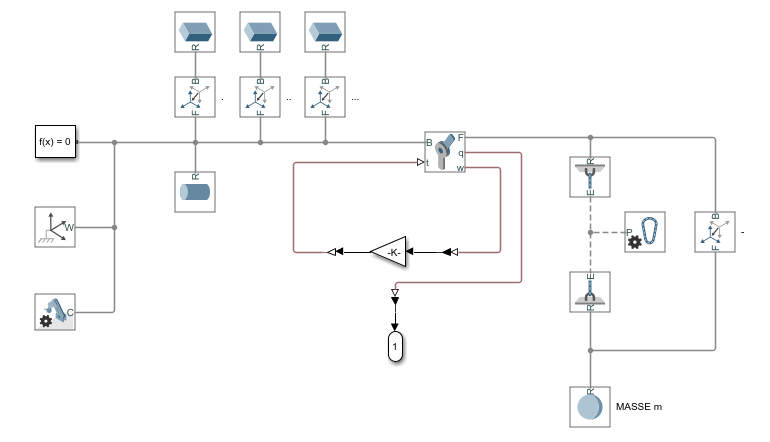

$\Rightarrow$**Résultat :** 

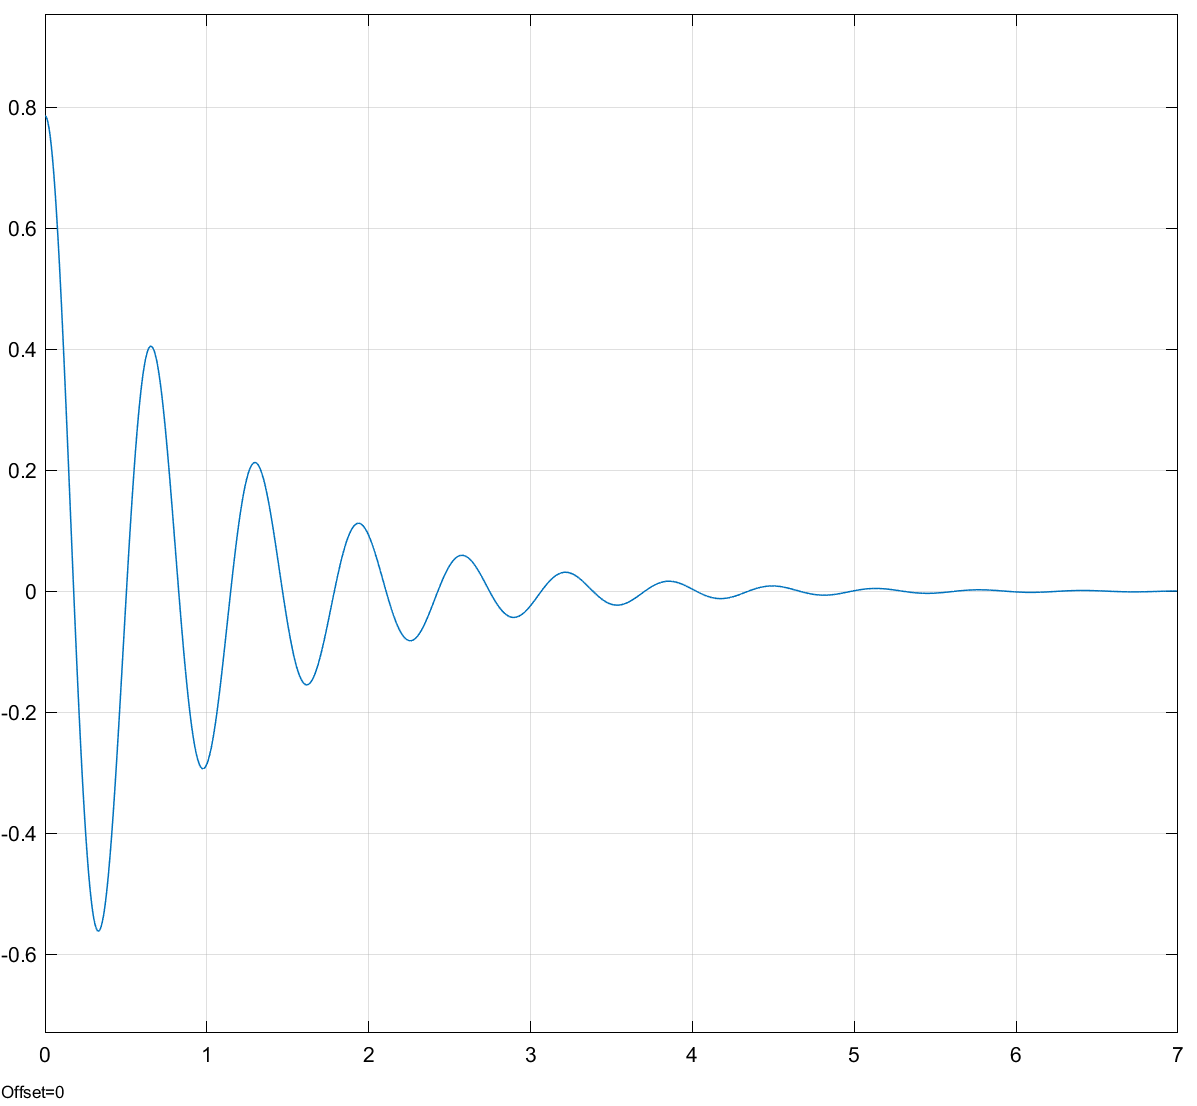

avec $$$
\ \left\{
    \begin{array}{ll}
        \theta~\textit{(en radian) en ordonnée}\\
         \textit{t}~\textit{(en seconde) en abscisse}\\
    \end{array}
\right.
$$$ 

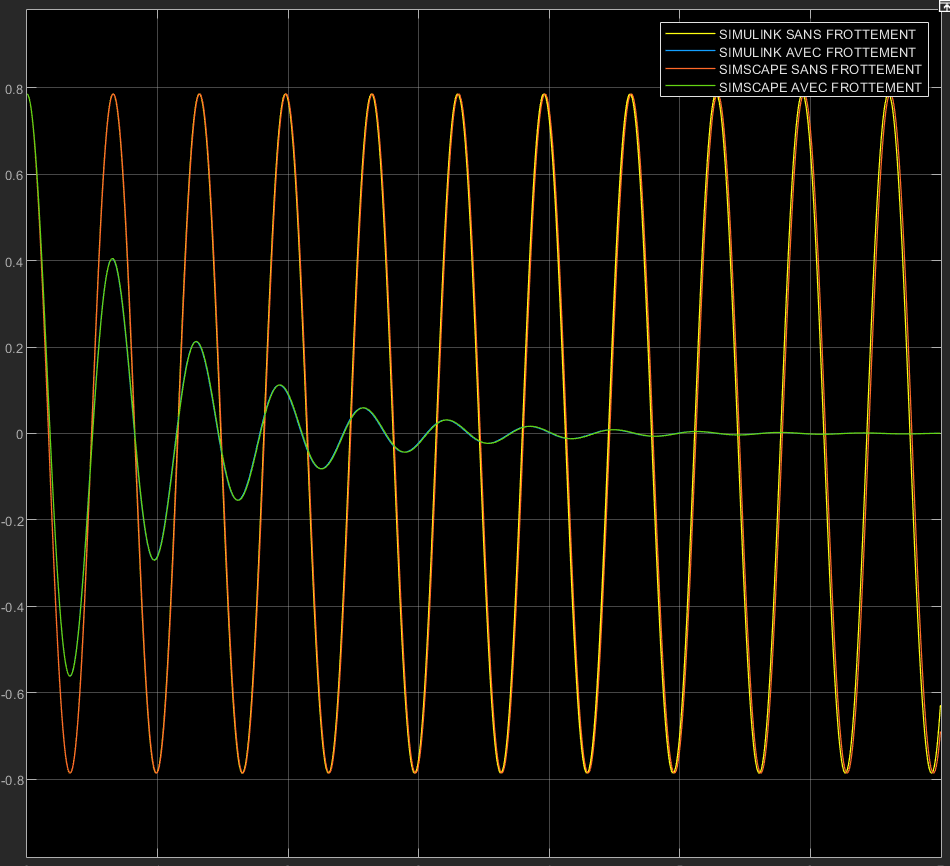

En conclusion, on remarque que nos courbes obtenues via SIMULINK, avec et sans frottement, se superposent avec celles de notre modèle SIMSCAPE. Cela nous conduit à considérer que les différents modèles que nous avons établis sont vérifiables et correctes.

*FIN DU SUJET*